clc; clear; close all;

%Tuned Mass Damper

%% ---------- CASE 1: TMD only (adds 1 DOF) ----------
ma = 1E6; % TMD mass
ka = 2.89E8; % Tuned to w = 15 rad/s

% Define the number of floors in the building
n = 11; % Change the number of floors
E = 30e9; % Elastic modulus in Pascals (Pa)
g = 9.81;
floor_mass = round(1600E6/g/79);
Mass = floor_mass * ones(n,1)'; % Masses of each floor in kg
Mass(11) = ma;
Height = 4 * ones(n,1)'; % Heights of each floor in meters
Inertia = 1.5^4/12 * ones(n,1); % Moment of inertia in m^4
k_values = 12 * 12 * E * Inertia ./ Height.^3; % Four Spring In Each Floor
k_values(11) = ka;

M = diag(Mass);
K = zeros(n);
for i = 1:n-1
    K(i,i) = k_values(i) + k_values(i+1);
    K(i,i+1) = -k_values(i+1);
    K(i+1,i) = -k_values(i+1);    
end
K(n,n) = k_values(n);

%Eigen Value Problem
[U,D] = eig(K,M);
w1 = D(1,1); w2 = D(2,2);
syms alpha beta
% Give damping ration = 5%
eq1 = 0.05 == 0.5*(alpha/w1 + beta*w1);
eq2 = 0.05 == 0.5*(alpha/w2 + beta*w2);
[a,b] = solve(eq1,eq2);
a = vpa(a)

$$a = 14.161746618617049405315305706681$$

b = vpa(b)

$$b = 0.00016171539206959882683882214543372$$

% M_c = 2967781623447.234403808909534589 * M; 
% K_c = 1.0000000000000003068988425448726 * K;
[U,D] = eig(K,M);
omega_n = sqrt(diag(D));
x_0 = zeros(n,1); % initial condition
v_0 = zeros(n,1); % initial condition
r_0 = U'*M*x_0;
rdot_0 = U'*M*v_0;
R_i = [r_0 rdot_0];

fprintf('Stiffness matrix [K] in N/m:\n');

Stiffness matrix [K] in N/m:


disp(K);

   1.0e+10 *

    5.6953   -2.8477         0         0         0         0         0         0         0         0         0
   -2.8477    5.6953   -2.8477         0         0         0         0         0         0         0         0
         0   -2.8477    5.6953   -2.8477         0         0         0         0         0         0         0
         0         0   -2.8477    5.6953   -2.8477         0         0         0         0         0         0
         0         0         0   -2.8477    5.6953   -2.8477         0         0         0         0         0
         0         0         0         0   -2.8477    5.6953   -2.8477         0         0         0         0
         0         0         0         0         0   -2.8477    5.6953   -2.8477         0         0         0
         0         0         0         0         0         0   -2.8477    5.6953   -2.8477         0         0
         0         0         0         0         0         0         0   -2.8477    5.6953   -2.84


fprintf('Mass matrix [M] in kg:\n');

Mass matrix [M] in kg:


disp(M);

     2064543           0           0           0           0           0           0           0           0           0           0
           0     2064543           0           0           0           0           0           0           0           0           0
           0           0     2064543           0           0           0           0           0           0           0           0
           0           0           0     2064543           0           0           0           0           0           0           0
           0           0           0           0     2064543           0           0           0           0           0           0
           0           0           0           0           0     2064543           0           0           0           0           0
           0           0           0           0           0           0     2064543           0           0           0           0
           0           0           0           0           0         


Lambda = char(hex2dec('039B'));                     
fprintf(['Sprectal Matrix [' Lambda '] \n']);

Sprectal Matrix [Λ] 


disp(U'*K*U);

   1.0e+04 *

    0.0220   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0399   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0000    0.2760   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000    0.7388   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000    0.0000   -0.0000    1.3814    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000    0.0000    2.1464   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    2.9660    0.0000    0.0000   -0.0000   -0.0000
   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    3.7673   -0.0000    0.0000   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    4.4791   -0.00

Modal Analysis of Based Excitation

a = 27.68876706408824368131489359933;
b = 0.000032894521560077955830320103241098;
% There are some problems with type of matrix C
C = a*M + b*K;
M_modal = U' * M * U; % Should be identity matrix
C_modal = U' * C * U;
K_modal = U' * K * U % Should be spectral matrix

K_modal = 1.0e+04 *

    0.0220   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0399   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0000    0.2760   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000    0.7388   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000    0.0000   -0.0000    1.3814    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000    0.0000    2.1464   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    2.9660    0.0000    0.0000   -0.0000   -0.0000
   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    3.7673   -0.0000    0.0000   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    4.4791 

% Earthquake
w = 17;
f = 2*pi*w;
fs = 2.5*f; %Sampling Frequency
t_end = 30;
number_of_t = t_end * fs;
tspan = linspace(0,t_end,number_of_t);
y = 0.2 * sin(w*tspan);
ay = 0.2 * w^2 * sin(w*tspan);
r = zeros(n,length(tspan));
gamma = -U'* M * ones(n,1);
for i = 1:n
    omega_i = omega_n(i);
    zw_i = a + b * omega_i^2;
    gamma_i = gamma(i);
    eom_ode = @(t, r) eom(t,r,omega_i,zw_i,gamma_i,w);
    r_i = R_i(i,:); % Initial conditions: [r_i(0); rdot_i(0)]  
    [t, y] = ode45(eom_ode, tspan, r_i);
    r(i,:) = y(:,1)';
end

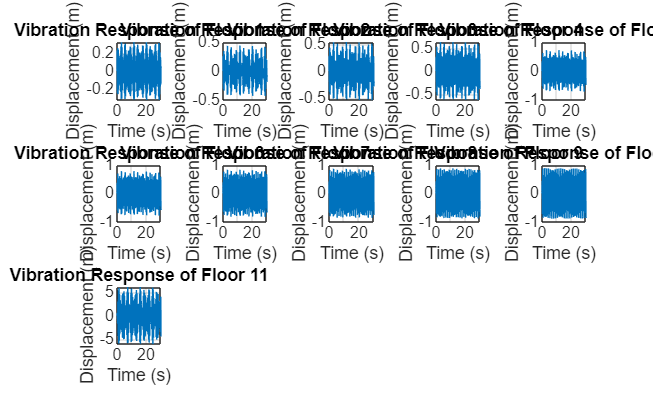

x = U*r;
xg = 0.2 * sin(w*tspan); % Subject to change by excitation
x = x + xg; %Change from relative displacement to absolute

%Plot response of each floor in subplots
figure;

for floor = 1:n
    subplot(3, round(n/2,0)-1, floor);
    plot(t, x(floor, :), 'LineWidth', 0.5);
    title(['Vibration Response of Floor ', num2str(floor)]);
    xlabel('Time (s)');
    ylabel('Displacement (m)');
    grid on;
end
% Optional: Maximize figure window for better visibility
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 1]);

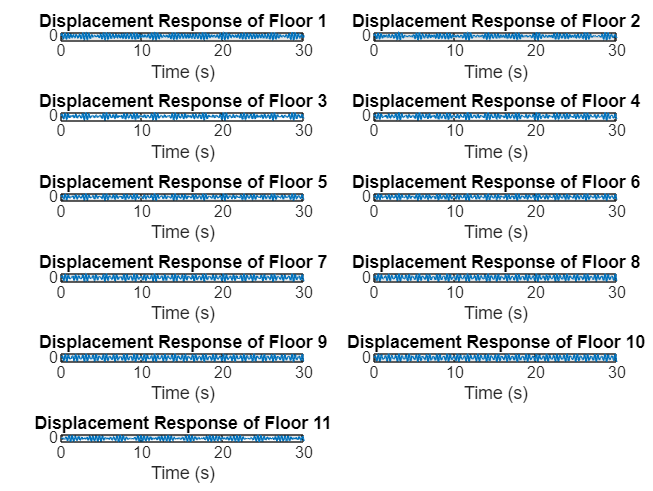


%Plot response of each floor in subplots
figure;
tiledlayout(6,2, 'TileSpacing', 'compact', 'Padding', 'compact');

for i = 1:n
    nexttile;
    plot(t, x(i, :));
    xlabel('Time (s)');
    ylabel('Displacement (m)');
    title(['Displacement Response of Floor ', num2str(i)]);
    grid on;
    axis tight;
end

function rdot = eom(t,r,omega_i,zw_i,gamma_i,w)
    ay = -0.2 * w^2 * sin(w*t);
    rdot = zeros(2,1);
    rdot(1) = r(2);
    rdot(2) = -zw_i*rdot(2) - omega_i^2*r(1) + gamma_i*ay;
end